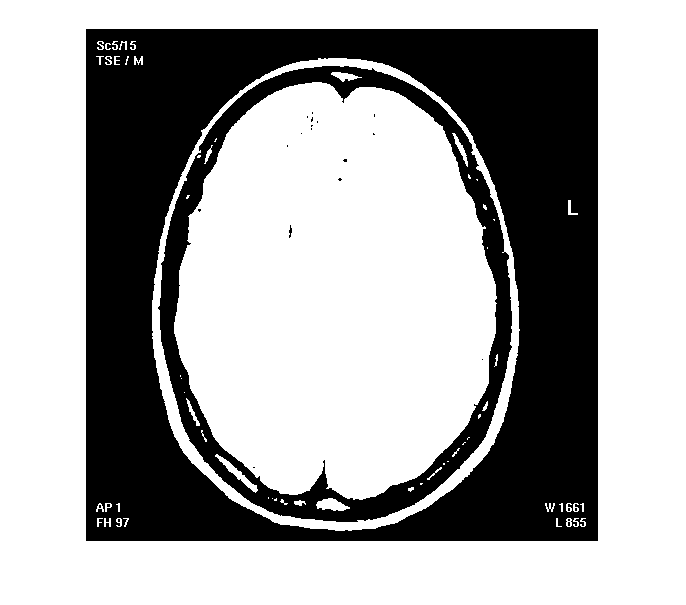

im = imread('IM_00240.TIF');
imshow(im)
f = im2uint8(im);
count =0;
T = mean2(f);
done = false;
while ~done
count = count +1;
g = f > T;
Tnext = 0.5*(mean(f(g)) +mean(f(~g)));
done = abs(T -Tnext)<0.5;
T = Tnext;
end
g = im2bw(f, T/255);
figure,imshow(g)

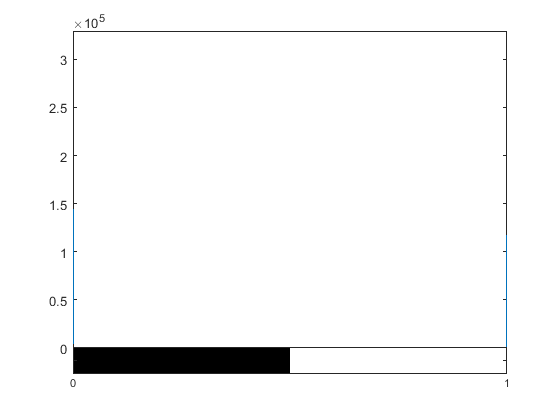

%figure,imhist(g)